mri reface

ref_dir = 'E:\work_Code\Matlab\ZYS\Brain_Science\from_github\mri_reface_0.3\mri_reface\mri_reface\fsroot\images\';
mri_ref = MRI_read_Data([ref_dir,'MCALT_FaceTemplate_T1.nii']);

apply data = data - -0.45206
sMRI [177,121,187] res:[1.5,1.5,1.5]


samp_dir = 'E:\work_Code\Python\MiniProjects\from_github\Vox2Cortex-main\dataset_root\dataset_raw\001\';
mri_defa_file = [samp_dir,'mri_deface.nii.gz'];

mri_defa = MRI_read_Data(mri_defa_file);

sMRI [320,208,320] res:[0.8,0.8,0.8]


sMov = mri_ref; sFix = mri_defa;

tic
[sReg,geomtform,register_info] = MRI_affine_register(sMov,sFix,'type','affine','if_fast',1,'repeat_num',1);
geomtform.A(1:3,4)'

ans =       -7.3167      -1.3479      -63.734


toc

历时 4.455619 秒。


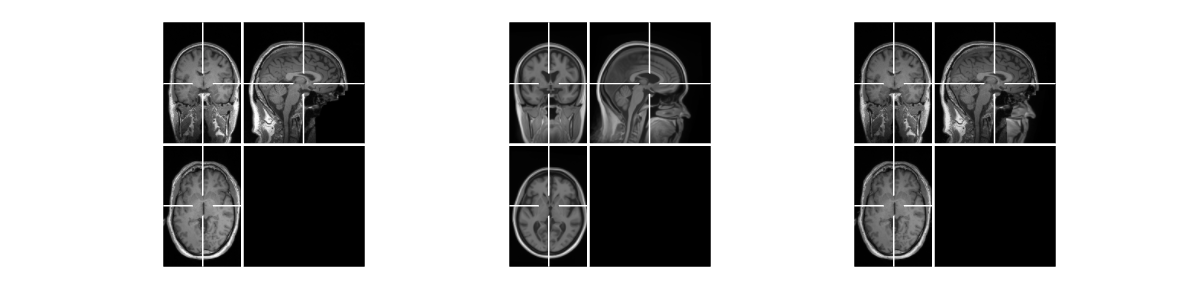

volume size = [320, 208, 320], voxsize = [0.8, 0.8, 0.8];  show size = [320, 208, 320], pixsize = 0.8
volume size = [320, 208, 320], voxsize = [0.8, 0.8, 0.8];  show size = [320, 208, 320], pixsize = 0.8
volume size = [320, 208, 320], voxsize = [0.8, 0.8, 0.8];  show size = [320, 208, 320], pixsize = 0.8


mask_defa = sFix.data==0;
sFuse = sFix; sFuse.data(mask_defa) = sReg.data(mask_defa);

figure;
next; plot_mri({sFix,sReg,sFuse},'off','cmap','gray'); lay_fig([12,3])

tic
[sReg,trans_params,def_field] = MRI_register(sMov,sFix,'reg_type','nonrigid', ...
    'remake_sz',1,'auto_params',5,'get_field',0,'warp_byField',0);

sMRI [320,208,320] res:[0.8,0.8,0.8]
apply data = data - -0.23231
sMRI [177,121,187] res:[1,1,1]
sMRI [177,121,187] res:[1,1,1]
    FinalGridSpacingInPhysicalUnits: [32 32 32]
                   SampleRegionSize: [32 32 32]
                  ResultImageFormat: 'nii.gz'

    1: E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\Parameter\para-Nonrigid3D-OpenCL.txt    

    {'E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\\elastix\elastix'                        }
    {'f "E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\\Images\fix.nii.gz"'                  }
    {'m "E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\\Images\mov.nii.gz"'                  }
    {'out E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\RegResult'                           }
    {'p "E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\Parameter\para-Nonrigid3D-OpenCL.txt"'}

 
elastix is started at Fri Jan 12 02:14:21 2024

disp_toc

  |->  using 21.6s [==============================================] 2024-01-12 02:14:40


sPET = sReg;


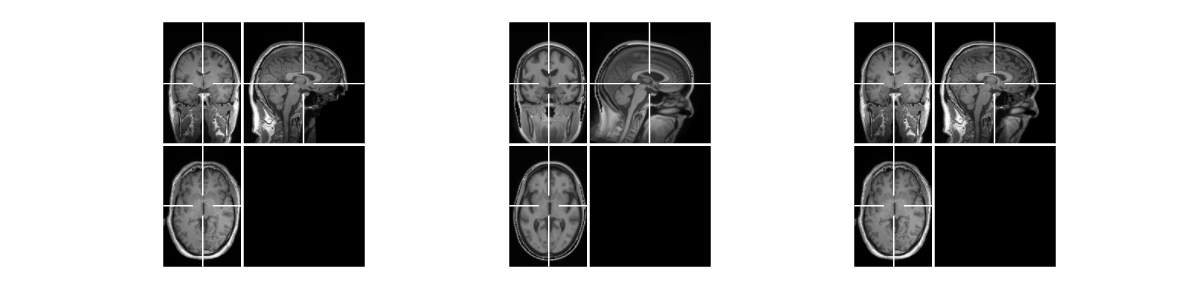

volume size = [320, 208, 320], voxsize = [0.8, 0.8, 0.8];  show size = [320, 208, 320], pixsize = 0.8
volume size = [320, 208, 320], voxsize = [0.8, 0.8, 0.8];  show size = [320, 208, 320], pixsize = 0.8
volume size = [320, 208, 320], voxsize = [0.8, 0.8, 0.8];  show size = [320, 208, 320], pixsize = 0.8


mask_defa = sFix.data==0;
sReg.data = single(sReg.data); sFix.data = single(sFix.data);
data1 = sReg.data(~mask_defa); data2 = sFix.data(~mask_defa);
sFuse = sFix; temp = (sReg.data-mean(data1))*std(data2)/std(data1)+mean(data2);

mask_defa_sm = 1.5*imgaussfilt3(single(mask_defa),5); mask_defa_sm(mask_defa_sm>1) = 1;
sFuse.data = temp.*mask_defa_sm + sFix.data.*(1-mask_defa_sm);

mri_raw = sFuse;

figure;
next; plot_mri({sFix,sReg,sFuse},'off','cmap','gray'); lay_fig([12,3])

crop via registration

tic
mri_dir = 'D:\File\work_file\Dataset\Brain\openFCD\sub-00044\T1_rb\';
sMRI = MRI_read_Data([mri_dir,'T1.nii.gz']);

sMRI [320,192,320] res:[0.8,0.8,0.8]


% T_map = MRI_read_Data([mri_dir,'mni2sub.map.nii.gz']);
T_invmap = MRI_read_Data([mri_dir,'sub2mni.map.nii.gz']);

sMRI [229,193,193,3] res:[1,1,1]


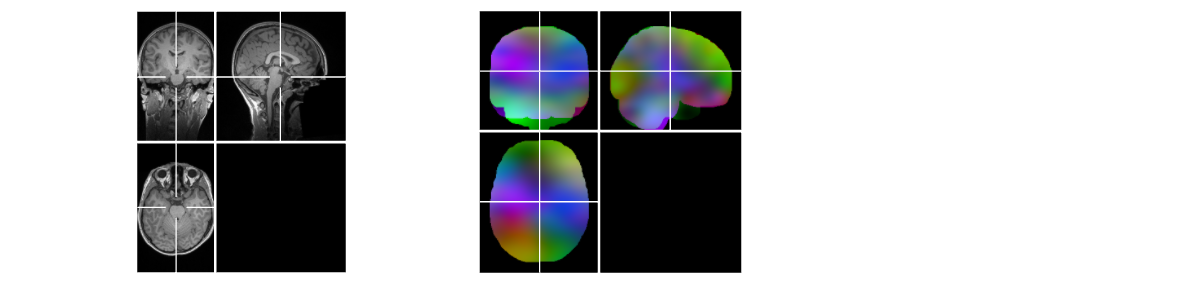

volume size = [320, 192, 320], voxsize = [1, 1, 1];  show size = [320, 192, 320], pixsize = 1
volume size = [229, 193, 193], voxsize = [1, 1, 1];  show size = [229, 193, 193], pixsize = 1



figure; lay_sub(1,3)
% svreg.map 描绘的是配准结果图像对应的原始图像坐标场
next; plot_mri({sMRI,T_invmap},'off','if_detrend',1); lay_fig([12,3])

mri = T_invmap.data;
[ny,nx,nz,nc] = size(mri);
[X,Y,Z] = meshgrid(1:nx,1:ny,1:nz);
mask = mean(mri,4)>0;
T_affine.data = 0*mri;
for i = 1:3
    mri_val = mri(:,:,:,i);
    regress_val = [X(mask),Y(mask),Z(mask),0*X(mask)+1];
    regress_b = regress(mri_val(mask),regress_val);
    T_affine.data(:,:,:,i) = regress_b(1)*X+regress_b(2)*Y+regress_b(3)*Z+regress_b(4);
end
T_affine.data = T_affine.data.*(1-mask)+mri.*mask;
sMRI_warp = MRI_warp(T_affine,sMRI,'BST');
sMRI_warp.data(isnan(sMRI_warp.data)) = 0;
mri_raw = MRI_read_Data(sMRI_warp,'voxsize',[1,1,1]);

sMRI [229,193,193] res:[1,1,1]


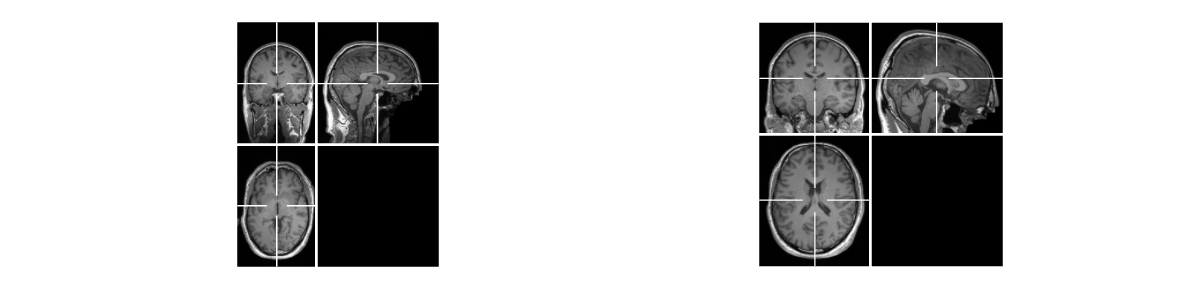

volume size = [320, 208, 320], voxsize = [1, 1, 1];  show size = [320, 208, 320], pixsize = 1
volume size = [229, 193, 193], voxsize = [1, 1, 1];  show size = [229, 193, 193], pixsize = 1



figure;
next; plot_mri({sMRI,sMRI_warp},'off','cmap','gray'); lay_fig([12,3])

% mri_raw = MRI_read_Data('E:\work_Code\Python\MiniProjects\from_github\Vox2Cortex-main\dataset_root\dataset_raw\001\mri_raw.nii.gz');
voxin_sz = [218 182 182];

mri_crop = mri_raw;

函数或变量 'mri_raw' 无法识别。

mri_crop = MRI_func_ROI(mri_raw,'crop',{':',':',[1:193]});
mri = MRI_func_ROI(mri_crop,'imresize3',voxin_sz);
mri = MRI_read_Data(mri,'voxsize',[1,1,1]); mri.T_mat = [];
% MRI_save_File(mri,'E:\work_Code\Python\MiniProjects\from_github\Vox2Cortex-main\dataset_root\dataset_raw\T1\mri.nii.gz');

toc

surf_file = 'E:\work_Code\Python\MiniProjects\from_github\Vox2Cortex-main\experiments\public_model\test_template_42016_DATASET_NAME\meshes\sub-00003_epoch76_struc2_meshpred.ply';
surf_ply = Surf_read_Data(surf_file);
surf_ply.Vertices = (surf_ply.Vertices./voxin_sz([2,1,3]) + 1/2).*mri_raw.shape;
% Surf_save_File(surf_ply);

surf_ply_warp = Surf_warp(surf_ply,T_invmap);
surf_ply_warp.Vertices = surf_ply_warp.Vertices.*sMRI.voxshape;

figure; colormap(gray)
next; slice_mri(mri_raw); hold on; plot_surf(surf_ply); view(125,20)

sMRI [229,193,193] res:[1,1,1]


next; slice_mri(sMRI); hold on; plot_surf(surf_ply_warp); view(125,20)

sMRI [320,208,320] res:[0.8,0.8,0.8]


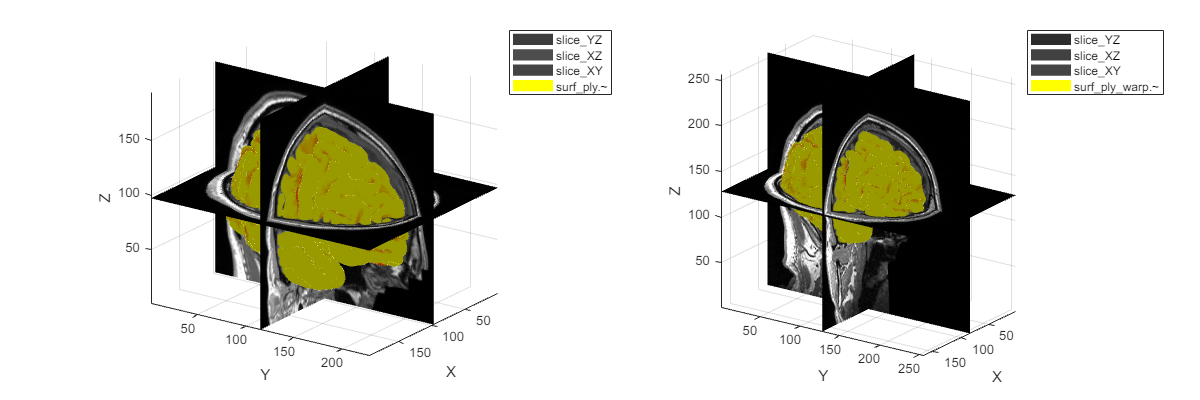

lay_fig([12,4])

surf_file = 'D:\File\work_file\Dataset\Brain\openFCD\sub-00003\surf\T1_reg.DL.right.pial.ply';
surf_ply = Surf_read_Data(surf_file);

skPial1 = Surf_voxelise(surf_ply,'mode',0,'ref',mni_gray,'overlap',1);
% skPial2 = Surf_voxelise(surf_ply,'mode',1,'ref',mni_gray,'overlap',0);
% plot_mri(mri.data + 10000*skPial.data)

val_curv = Surf_func_Val(surf_ply,'curvature','fine',0);
surf_ply.vColor = []; surf_ply.Labels = val_curv.k1;

T1reg = MRI_read_Data([mri_dir,'T1.pvc.frac_reg.nii.gz']);

sMRI [229,193,193] res:[1,1,1]



GM = 1 - 2*abs(T1reg.data - 1); 
GM(GM<0) = 0;

T1sk = MRI_read_Data([mri_dir,'../surf/T1_reg.pial_label.nii.gz']);

sMRI [229,193,193] res:[1,1,1]



bw = T1sk.data == 6;
% bw_thin = imgaussfilt3(single(bw),1) - 0.5; bw_thin(bw_thin<0) = 0;
bw_thin = imerode(bw,true(3));

LAB = T1reg.data;
CSF = imgaussfilt3(LAB,3)>0;
CSFGM = CSF.*(LAB<=1);

out_dist = MRI_func_ROI(CSFGM==0,'dist_map');
out_dist = out_dist.data;

TF = islocalmax(out_dist,1) + islocalmax(out_dist,2) + islocalmax(out_dist,3);
GMthin = GM.^1.*(1-(TF>0));

TF = imgradient3(out_dist);
TF = TF - 16; TF(TF<0) = 0; TF(TF>27) = 27;
GMthin = GM.*TF/27;


tic
load LineSegments

param.useParpool = true;
[Thickness, SkeletonDistance] = MLI_thickness(GMthin, L,param);

Direction #1 out of 193
Direction #1 out of 193
Direction #1 out of 193
Direction #1 out of 193
Direction #1 out of 193
Direction #1 out of 193
Direction #1 out of 193
Direction #1 out of 193
Direction #1 out of 193
Direction #1 out of 193
Direction #1 out of 193
Direction #2 out of 193
Direction #2 out of 193
Direction #3 out of 193
Direction #2 out of 193
Direction #2 out of 193
Direction #3 out of 193
Direction #2 out of 193
Direction #3 out of 193
Direction #2 out of 193
Direction #3 out of 193
Direction #2 out of 193
Direction #3 out of 193
Direction #1 out of 193
Direction #2 out of 193
Direction #2 out of 193
Direction #4 out of 193
Direction #5 out of 193
Direction #6 out of 193
Direction #3 out of 193
Direction #4 out of 193
Direction #2 out of 193
Direction #3 out of 193
Direction #4 out of 193
Direction #5 out of 193
Direction #6 out of 193
Direction #4 out of 193
Direction #5 out of 193
Direction #2 out of 193
Direction #4 out of 193
Direction #5 out of 193
Direction #4 out

toc

历时 14.741439 秒。


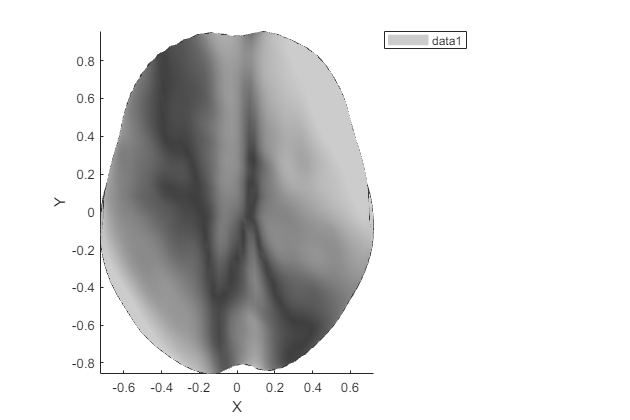

D = amp(Thickness,0).^1.75;

V = amp(LAB,0);
rgb = hsv2rgb(cat(3,D(:),0.5*D(:),V(:)));
rgb = reshape(squeeze(rgb),[size(D),3]);

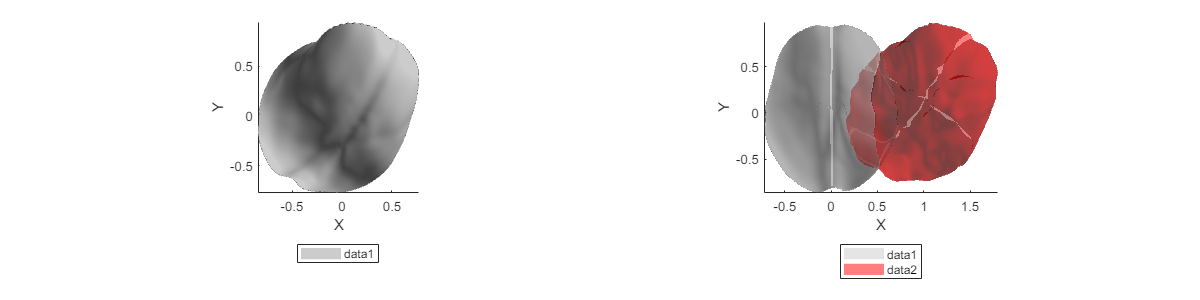

f3 = reshape(mni_bnd8c.Vertices,[100 100,3]);
f4 = imresize(f3,[50,99]);
f4 = (f4 - mean(f4,[1,2]))/100;

figure; next; h = plot_surface(f4);

rotate(h,[1,1,0],20)
rotate(h,[0,0,1],-35)

f5 = cat(3,h.XData+1,h.YData,h.ZData);
f5 = f5 + 0.05*imresize3(rand(20,20,3),size(f5));
next; plot_surface(f4,'alpha',0.5); hold on; plot_surface(f5,'color',[1,0,0],'alpha',0.5);
lay_fig([12,3])

surf_file = 'D:\File\work_file\Dataset\Brain\openFCD\sub-00002\surf\T1_reg.DL.right.pial.ply';
surf_ply = Surf_read_Data(surf_file);

val_curv = Surf_func_Val(surf_ply,'curvature','fine',0);
surf_ply.vColor = []; surf_ply.Labels = val_curv.k1;

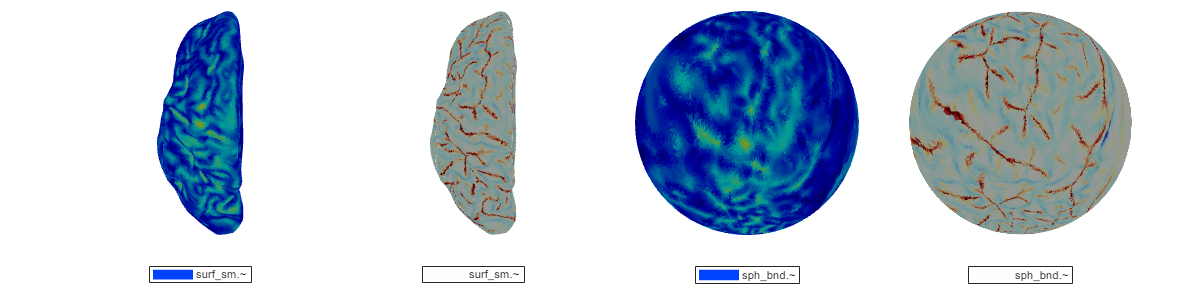

[surf_sm,~,vdist] = Surf_smooth(surf_ply,'iter',100,'type',3,'calc_dist',1);
[sph_bnd] = Surf_func_ROI(surf_ply,'mapping_sphere','fine',0,'get_field',0);

figure; lay_sub(1,4)
next; colormapa(jet); plot_surf(surf_sm,'colors',vdist); axis off
next; colormapa(cmap_sign); plot_surf(surf_sm,'colors',val_curv.k1); caxis([-1,1]); axis off
next; colormapa(jet); plot_surf(sph_bnd,'colors',vdist); axis off
next; colormapa(cmap_sign); plot_surf(sph_bnd,'colors',val_curv.k1); caxis([-1,1]); axis off
lay_fig([12,3]); lay_linkview(gcf,'view')

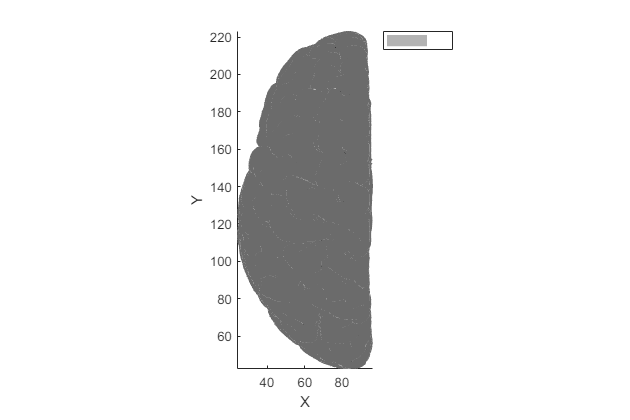

surf_file = 'E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\MNI152_FSL\surf\lh.pial';
[V,F] = read_surf(surf_file);
figure;
next; plot_surf(struct('Vertices',V+[90,126,72],'Faces',F+1));

f1 = permute(f4,[3,1,2]);
f2 = permute(f5,[3,1,2]);
save('E:\work_Code\Python\MiniProjects\from_github\surfaceRegistration-master\ShapeData\bumpSphere.mat','f1','f2')